 clc;
 clear; 
close all; % Clear command window, workspace, and close all figures.
 disp('input sound'); % Display a message indicating that input sound is being processed.

input sound


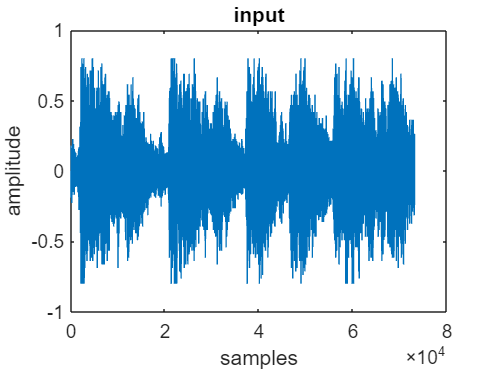

 load handel.mat; % Load the 'handel.mat' file which contains the audio data and sample rate.
 fs = Fs; % Retrieve the sampling rate from the loaded data.
 y = y(:,1); % Use only the first channel of audio if it's stereo.
 sound(y); % Play the original sound.
 pause(10); % Wait for 10 seconds.
 figure, plot(y); % Create a new figure and plot the audio data.
 title('input');
 xlabel('samples');
 ylabel('amplitude');

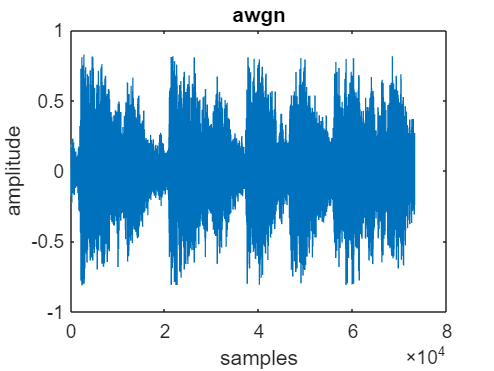

 y = awgn(y, 40); % Add white Gaussian noise to the signal with an SNR of 40 dB.
 noi = y; % Store the noisy signal for later use.
 figure, plot(y); % Plot the noisy signal.
title('awgn');
 xlabel('samples');
 ylabel('amplitude');

 disp('playing added noise...');

playing added noise...


 sound(y); % Play the noisy signal.
 pause(10);
 hlpf = fdesign.lowpass('Fp,Fst,Ap,Ast', 3.0e3, 3.5e3, 0.5, 50, fs);
 D = design(hlpf); % Design a low-pass filter based on specifications.
 freqz(D); % Display the frequency response of the designed filter.
 x = filter(D, y); % Apply the low-pass filter to the noisy signal.
 disp('playing denoised sound');

playing denoised sound


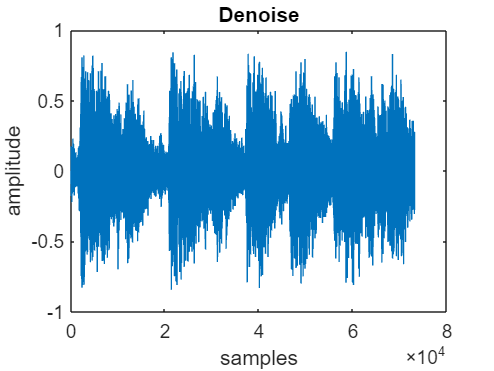

 figure, plot(x); % Plot the filtered (denoised) signal.
 title('Denoise');
 sound(x, fs); % Play the denoised signal.
 xlabel('samples');
 ylabel('amplitude');

 pause(10);
 I = 1/fs; % Inverse of sampling frequency, not used in this script.
 len = length(x);
 p = log2(len);
 p = ceil(p);
 N = 2^p;
 f1 = fdesign.bandpass(['Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2'], 2000, 3000, 4000, 5000, 60, 2, 60, 2*fs);
 hd = design(f1, 'equiripple'); % Design a bandpass filter.
 y = filter(hd, x); % Apply the bandpass filter to the denoised signal.
 freqz(hd); % Display the frequency response of the bandpass filter.
 y = y * 100; % Increase the amplitude of the filtered signal.
 disp('playing frequency shaped');

playing frequency shaped


 sound(y, fs); % Play the frequency-shaped signal.
 pause(10);
 disp('amplitude shaper')

amplitude shaper


 out1 = fft(y); % Perform a Fourier transform on the frequency-shaped signal.
 phse = angle(out1); % Extract the phase information.
 mag = abs(out1) / N; %Compute the magnitude spectrum and normalize by N.
 [magsig, ~] = size(mag);
 threshold = 1000;
 out = zeros(magsig, 1);
 for i = 1:magsig/2
 if (mag(i) > threshold)
 mag(i) = threshold;
 mag(magsig-i) = threshold;
end
 out(i) = mag(i) * exp(j * phse(i));
 out(magsig-i) = out(i);
 end
 outfinal = real(ifft(out1)) * 10000; % Perform an inverse FFT and scale up.
 disp('playing amplitude shaped');

playing amplitude shaped


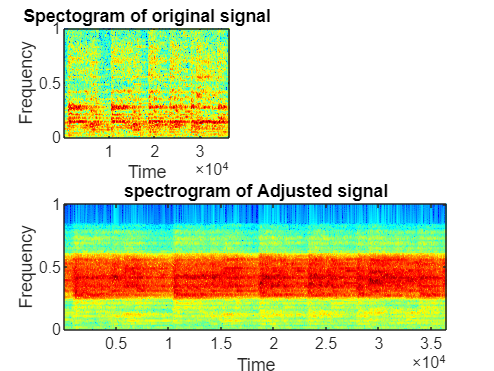

 sound(outfinal, fs); % Play the amplitude-shaped signal.
 pause(10);
 load handel.mat % Attempt to load a non-existent file, causing an error.
 figure;
 subplot(2,2,1);
 specgram(noi);
 title('Spectogram of original signal');
 subplot(2,1,2)
 specgram(outfinal);
 title('spectrogram of Adjusted signal')